# Project 1: Numerical ODEs

Ellie Suit and Ethan Tyler

## Problem 1


$$\frac{\textrm{dy}}{\textrm{dt}}=-2{\;t\;y}^2 ,y\left(0\right)=1$$


**(a)**

One can solve the above IVP using separation of variables, since the equation is separable. This can be seen by setting $p(t) = -2t$ and $q(y) = y^2$. It then takes on the form $dy/dt = p(t)q(y)$ and we can solve it using separation of variables. First we can rewrite it as


$$\frac{\textrm{dy}}{y^2 }=-2t\;\textrm{dt}$$


and integrating both sides with respect to the corresponding variable ($y$ or $t$) yields 

$-\frac{1}{y}=-\frac{2t^2 }{2}+C$. 

Solving the equation for $y$ thus yields 

$y=\frac{1}{t^2 +c}$. 

This is the general solution for the IVP, where $c$ is an arbituary constant dependent on the initial value. Plugging in $y(0) = 1$, we find that $c = -1$ and therefore


$$y=\frac{1}{t^2 +1}$$


is the solution to the IVP. 

**(b)**

Euler's method is a numerical approximation that uses discrete points to approximate a continuous curve. It is useful when we have a differential equation that we cannot solve exactly and must approximate the solution. It takes on the form

$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n +h*f\left(t_n ,\hat{y} {\;}_n \right)$, 

where $\hat{y}_{n}$ and $\hat{y}_{n+1}$ are the approximations of the $y$ values for grid points $n$ and $n+1$ respectfully, $h$ is the spacing between grid points, and $f$ is the derivative with respect to independent variable $t$ of a function $y$. Specifically for the purposes of this problem, the Euler approximation is 

$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n +h*\left(-2{t_n {\hat{y} }_n }^2 \right)$.

Therefore,

$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n -2\;{h\;t}_n \hat{y} {\;}_n^2$. 

**(c)**

The improved Euler's method is a numerical approximation that aims to reduce much of the error caused by the use of the tangent line in the Euler method. Namely, the Euler method uses only one point to determine the corresponding tangent line and hence the approximation of the location of the next point on the curve, whereas the improved Euler's method takes into account the slopes at each ends of a given time interval of length $h$ and determines the tangent line based on the average of these slopes. The result, using two points instead of one, is more effective and gives a better approximation for the location of the next point on the curve. 

$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n +h\;\left\lbrack \frac{f\left(t_n ,\hat{y} {\;}_n \right)+f\left(t_n +h,k_n \right)}{2}\right\rbrack$, 

where $k_n = \hat{y}_n + h f(t_n, \hat{y}_n)$. 

Therefore, for this specific problem, the improved Euler appears as 


$$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n +h\;\left\lbrack \frac{-2t_n {\hat{y} }_n^2 -2\;\left(t_n +h\right)\left(\hat{y} {\;}_n +h*\left(-2t_n {\hat{y} }_n^2 \right)\right)}{2}\right\rbrack$$


**(d)**

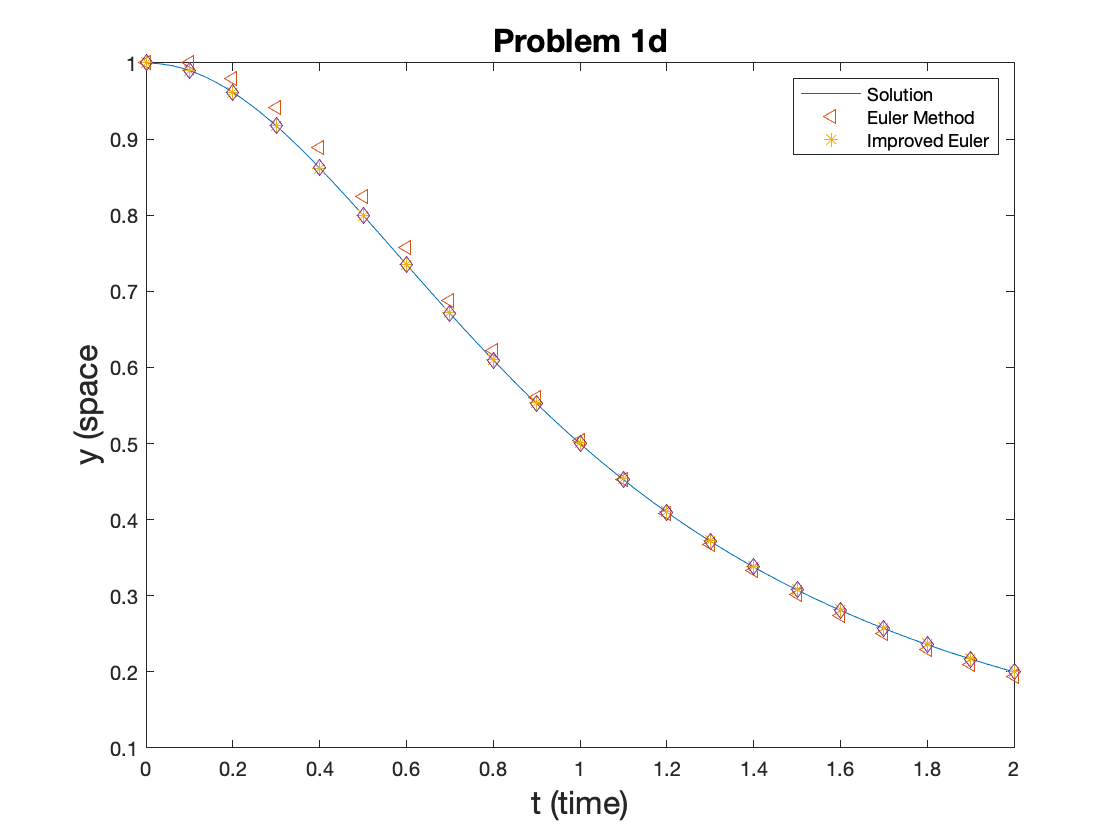

% code goes here
f = @(t, y) -2.*t.*y.^2; % define derivative 
soln1 = @(t) 1./(t.^2 + 1);  % define solution to diff eq 
t = linspace(0,2) ; % time grid 
h = 0.1; % step size 

[t_arr, y_arr] = myEuler(1, 0, f, 2/h, h);  % Euler solution 
[t_arr_imp, y_arr_imp] = myImprovedEuler(1, f, 2/h, h); % improved Euler solution 
[t_arr_rk, y_arr_rk] = myRK4(1,f,2/h, h); % RK4 solution

% plot using scatter 
figure
plot(t, soln1(t))
hold on
scatter(t_arr, y_arr, "Marker","<")
scatter(t_arr_imp, y_arr_imp, "Marker","*")
scatter(t_arr_rk, y_arr_rk, "Marker", "diamond")
legend("Solution", "Euler Method", "Improved Euler")
xlabel("t (time)", "FontSize",16)
ylabel("y (space", "FontSize", 16)
title("Problem 1d", "FontSize", 16)

The Euler method seems to be noticeably inaccurate towards the beginning and end portions of the range. The improved Euler method sticks to the solution much better than the Euler method. Similalrly, the RK4 method seems to stick to the curve more than the Euler method, appearing to be more accurate than the Euler method and similar to the improved Euler method. 

**(e) **(f) calculating the error: $E_n =\max \left|\;y\left(t_n \right)\;\;-y_n \right|$

% code goes here 
true_sol = soln1(linspace(0,2,2/h+1)); % evaluate the true solution from solving the diffeq 
euler_err = abs(true_sol - y_arr.');  % array of Euler errors |true solution - approximated solution| 

max_euler = max(euler_err); % maximum error 
max_euler

max_euler = 0.0263


imp_euler_err = abs(true_sol - y_arr_imp.'); % array of improved Euler errors 

max_improved = max(imp_euler_err); % maximum error 
max_improved

max_improved = 0.0010



rk_euler_err = abs(true_sol - y_arr_rk.');  % array of RK4 errors 

max_rk = max(rk_euler_err); % maximum error
max_rk

max_rk = 9.6764e-07

As calculated above, the global error for the Euler method is 0.0263, whereas the global error for the improved Euler method is 0.001 and the global error for the RK4 method is 9.68e-07. This behavior is consistent with the observations noted in part (d), where the improved Euler method and the RK4 method are more accurate than the Euler method. It is also clear from this data analysis that the RK4 method is more accurate than the improved Euler. 

**(f)**

 Rate of convergence found using $p\approx \log_2 \left(\frac{E_n \left(h\right)}{E_{2n} \left(\frac{h}{2}\right)}\right)$

% code goes here 
h2 = h/2; % new step size: half of the original 
true_sol2 = soln1(linspace(0,2,2/h2+1)); % true solution at this step size 
 
[t_arr2, y_arr2] = myEuler(1, 0, f, 2/h2, h2); % Euler approx 
[t_arr_imp2, y_arr_imp2] = myImprovedEuler(1, f, 2/h2, h2); % improved Euler approx
[t_arr_rk2, y_arr_rk2] = myRK4(1, f, 2/h2, h2); % RK4 approx 

% calculate the error as done before for each of the three methods
euler_err = abs(true_sol2 - y_arr2.'); 
max_euler2 = max(euler_err); 
conv_euler = log2(max_euler/max_euler2)

conv_euler = 1.0688

The order of convergence is 1.0688 for the Euler method. 

% error and order of convergence for improved Euler
euler_err_imp = abs(true_sol2 - y_arr_imp2.');
max_euler2_imp = max(euler_err_imp);

conv_euler_imp = log2(max_improved/max_euler2_imp)

conv_euler_imp = 2.0073

The order of convergence is 2.0073 for the improved Euler method. 

% error and order of convergence for RK4 method
rk4_err = abs(true_sol2 - y_arr_rk2.');
max_rk4err = max(rk4_err);

conv_rk4err = log2(max_rk/max_rk4err)

conv_rk4err = 4.0104

The order of convergence is 4.0104 for the RK4 method.

**(g)**

% code goes here 
f = @(t, y) -2.*t.*y.^2; % diff eq (pasted again) 
soln1 = @(t) 1./(t.^2 + 1); % solution to diff eq 
h1 = 0.1; % step size 
error = @(sol, arr) max(abs(sol - arr.')); % function to calculate error between solution (sol) and arr (approximation)
h = [h1 h1/2 h1/4 h1/8 h1/16 h1/32 h1/64]; % array of step sizes to be used in analysis 

% evaluate Euler for each of the step sizes
[t,arr1] = myEuler(1, 0, f, 2/h(1), h(1));
[t,arr2] = myEuler(1, 0, f, 2/h(2), h(2));
[t,arr3] = myEuler(1, 0, f, 2/h(3), h(3));
[t,arr4] = myEuler(1, 0, f, 2/h(4), h(4));
[t,arr5] = myEuler(1, 0, f, 2/h(5), h(5));
[t,arr6] = myEuler(1, 0, f, 2/h(6), h(6));
[t,arr7] = myEuler(1, 0, f, 2/h(7), h(7));

% find solution for the time grid used in the approximation (get the same
% size) 
s1 = soln1(linspace(0,2,2/h(1)+1));
s2 = soln1(linspace(0,2,2/h(2)+1));
s3 = soln1(linspace(0,2,2/h(3)+1));
s4 = soln1(linspace(0,2,2/h(4)+1));
s5 = soln1(linspace(0,2,2/h(5)+1));
s6 = soln1(linspace(0,2,2/h(6)+1));
s7 = soln1(linspace(0,2,2/h(7)+1));

% calculate convergence based on given formula
conv1 = log2(error(s1, arr1)/error(s2, arr2));
conv2 = log2(error(s2, arr2)/error(s3, arr3));
conv3 = log2(error(s3, arr3)/error(s4, arr4));
conv4 = log2(error(s4, arr4)/error(s5, arr5));
conv5 = log2(error(s5, arr5)/error(s6, arr6));
conv6 = log2(error(s6, arr6)/error(s7, arr7));

% create table of convergence with step size 
colnames = ["h", "Order of Convergence"];
table(h(2:end)', [conv1, conv2, conv3, conv4, conv5, conv6]', 'VariableNames',colnames)

ans = 6×2 table
        h        Order of Convergence
    _________    ____________________

         0.05           1.0688       
        0.025           1.0343       
       0.0125           1.0171       
      0.00625           1.0085       
     0.003125           1.0043       
    0.0015625           1.0021       


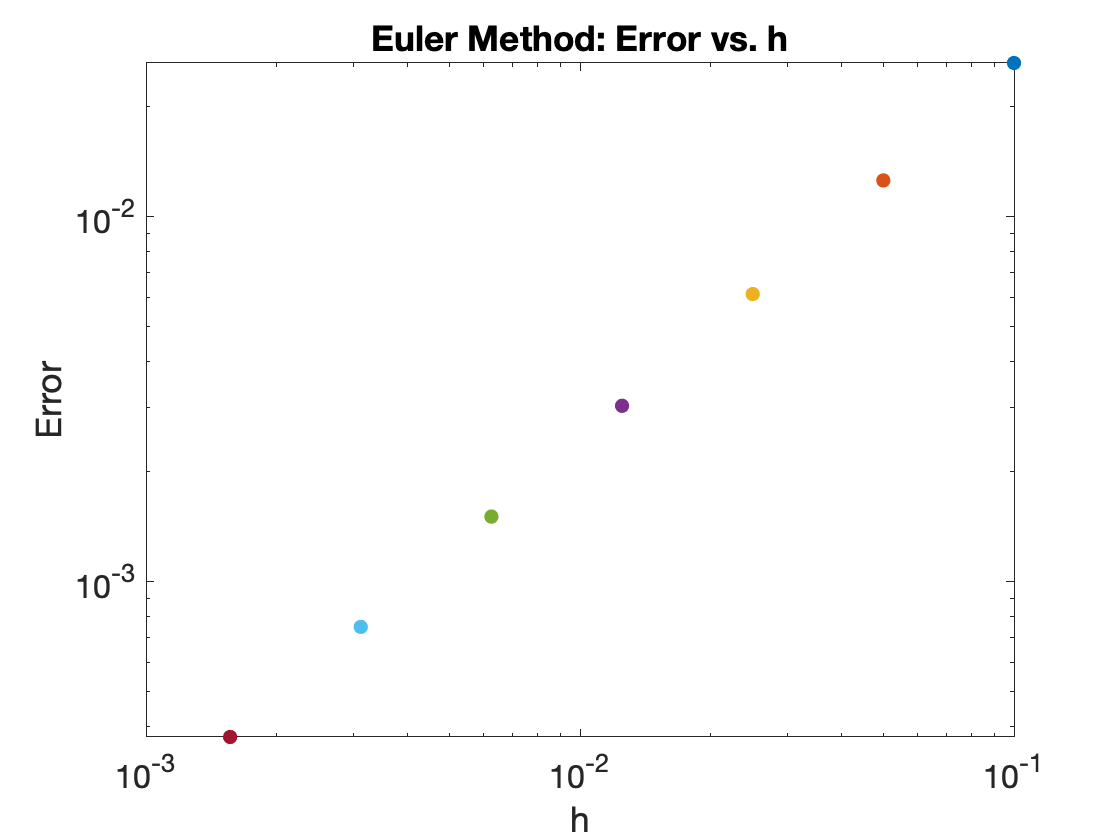


% plot log-log 
figure
loglog(h(1), error(s1, arr1),"MarkerSize", 20, "Marker",".")
hold on 
loglog(h(2), error(s2, arr2),"MarkerSize", 20, "Marker",".")
loglog(h(3), error(s3, arr3),"MarkerSize", 20, "Marker",".")
loglog(h(4), error(s4, arr4),"MarkerSize", 20, "Marker",".")
loglog(h(5), error(s5, arr5),"MarkerSize", 20, "Marker",".")
loglog(h(6), error(s6, arr6),"MarkerSize", 20, "Marker",".")
loglog(h(7), error(s7, arr7),"MarkerSize", 20, "Marker",".")


xlabel("h", "FontSize",16)
ylabel("Error", "FontSize",16)
title("Euler Method: Error vs. h")

% calculate the slope
slope = (log2(error(s1, arr1)) - log2(error(s7, arr7)))/(log2(h(1))-log2(h(7)))

slope = 1.0225

As shown in the calculations above the order of convergence between consecutive step sizes is $p = 1$. We also find that the slope of the line is $m = 1$. This agrees with our theory since we determined in class that the global error $E \propto h$ for the Euler method. Taking the $log$ of both sides we find that $\log(E) \propto $log(h)$. Therefore, $\log(E)$ should be directy proportional (have slope of $1$) to $h$. Therefore, the slope is $1$ as expected. In general, $E \propto h^p$ for an arbituary method, so in plotting this relationship in a log-log plot, $p$ will appear as the slope of the line of best fit in the error vs. $h$ plot. 

% do the same for the improved Euler method 
f = @(t, y) -2.*t.*y.^2;
soln1 = @(t) 1./(t.^2 + 1); 
h1 = 0.1;
error = @(sol, arr) max(abs(sol - arr.')); 
h = [h1 h1/2 h1/4 h1/8 h1/16 h1/32 h1/64];

[t,arr1] = myImprovedEuler(1, f, 2/h(1), h(1));
[t,arr2] = myImprovedEuler(1, f, 2/h(2), h(2));
[t,arr3] = myImprovedEuler(1, f, 2/h(3), h(3));
[t,arr4] = myImprovedEuler(1, f, 2/h(4), h(4));
[t,arr5] = myImprovedEuler(1, f, 2/h(5), h(5));
[t,arr6] = myImprovedEuler(1, f, 2/h(6), h(6));
[t,arr7] = myImprovedEuler(1, f, 2/h(7), h(7));

conv1 = log2(error(s1, arr1)/error(s2, arr2));
conv2 = log2(error(s2, arr2)/error(s3, arr3));
conv3 = log2(error(s3, arr3)/error(s4, arr4));
conv4 = log2(error(s4, arr4)/error(s5, arr5));
conv5 = log2(error(s5, arr5)/error(s6, arr6));
conv6 = log2(error(s6, arr6)/error(s7, arr7));
% generate table
colnames = ["h", "Order of Convergence"];
table(h(2:end)', [conv1, conv2, conv3, conv4, conv5, conv6]', 'VariableNames',colnames)

ans = 6×2 table
        h        Order of Convergence
    _________    ____________________

         0.05           2.0073       
        0.025           2.0039       
       0.0125           2.0021       
      0.00625            2.001       
     0.003125           2.0005       
    0.0015625           2.0002       


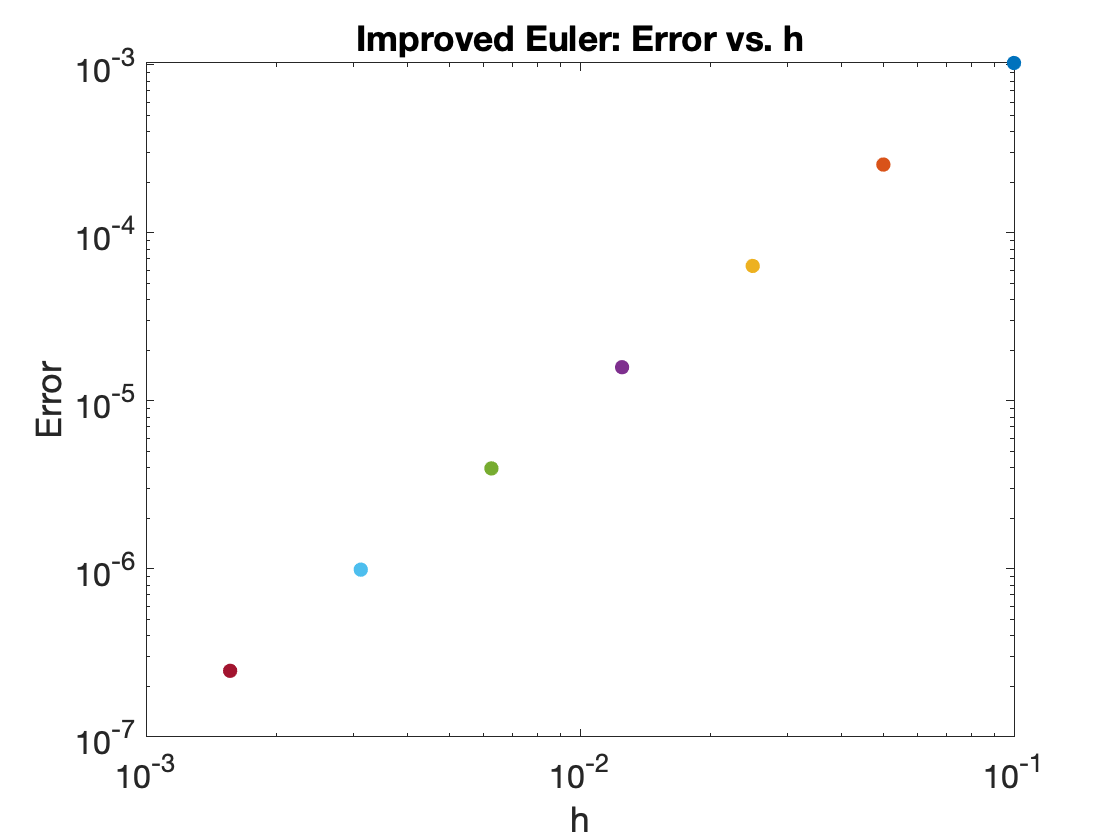

% plot log-log
figure
loglog(h(1), error(s1, arr1),"MarkerSize", 20, "Marker",".")
hold on 
loglog(h(2), error(s2, arr2),"MarkerSize", 20, "Marker",".")
loglog(h(3), error(s3, arr3),"MarkerSize", 20, "Marker",".")
loglog(h(4), error(s4, arr4),"MarkerSize", 20, "Marker",".")
loglog(h(5), error(s5, arr5),"MarkerSize", 20, "Marker",".")
loglog(h(6), error(s6, arr6),"MarkerSize", 20, "Marker",".")
loglog(h(7), error(s7, arr7),"MarkerSize", 20, "Marker",".")

xlabel("h", "FontSize",16)
ylabel("Error", "FontSize",16)
title("Improved Euler: Error vs. h", "FontSize",16)

% slope for improved Euler
slope = (log2(error(s1, arr1)) - log2(error(s7, arr7)))/(log2(h(1))-log2(h(7)))

slope = 2.0025

As shown in the calculations above the order of convergence between consecutive step sizes is $p = 2$. We also find that the slope of the line is $m = 2$. With similar logic to the Euler case, we know from our in-class calculations that the global error for the improved Euler method is $E \propto h^2$. Taking the log of both sides yields $\log(E) \propto 2\log(h)$. As a result, the slope of the line should be $2$ to agree with our order of convergence values listed in the corresponding table. This is exactly what we found. Therefore, the order of convergence in this case agrees with the theory and appears in the slope of the line of best fit in the $\log(E)$vs. $\log(h)$plot. 

% same analysis for RK4 
f = @(t, y) -2.*t.*y.^2;
soln1 = @(t) 1./(t.^2 + 1); 
h1 = 0.1;
error = @(sol, arr) max(abs(sol - arr.')); 
h = [h1 h1/2 h1/4 h1/8 h1/16 h1/32 h1/64];

[t,arr1] = myRK4(1, f, 2/h(1), h(1));
[t,arr2] = myRK4(1, f, 2/h(2), h(2));
[t,arr3] = myRK4(1, f, 2/h(3), h(3));
[t,arr4] = myRK4(1, f, 2/h(4), h(4));
[t,arr5] = myRK4(1, f, 2/h(5), h(5));
[t,arr6] = myRK4(1, f, 2/h(6), h(6));
[t,arr7] = myRK4(1, f, 2/h(7), h(7));

conv1 = log2(error(s1, arr1)/error(s2, arr2));
conv2 = log2(error(s2, arr2)/error(s3, arr3));
conv3 = log2(error(s3, arr3)/error(s4, arr4));
conv4 = log2(error(s4, arr4)/error(s5, arr5));
conv5 = log2(error(s5, arr5)/error(s6, arr6));
conv6 = log2(error(s6, arr6)/error(s7, arr7));
% table
colnames = ["h", "Order of Convergence"];
table(h(2:end)', [conv1, conv2, conv3, conv4, conv5, conv6]', 'VariableNames',colnames)

ans = 6×2 table
        h        Order of Convergence
    _________    ____________________

         0.05           4.0104       
        0.025           4.0087       
       0.0125           4.0045       
      0.00625           4.0025       
     0.003125           4.0015       
    0.0015625            3.999       


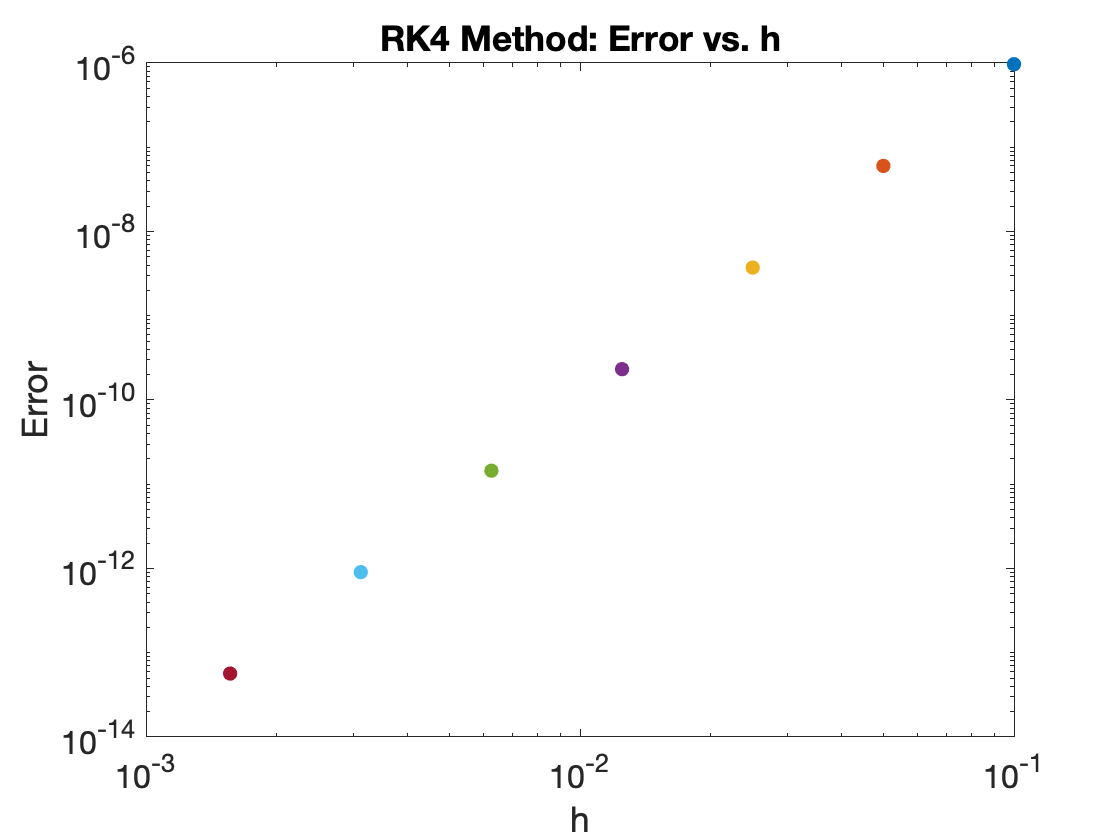

% plot log-log 
figure
loglog(h(1), error(s1, arr1),"MarkerSize", 20, "Marker",".")
hold on 
loglog(h(2), error(s2, arr2),"MarkerSize", 20, "Marker",".")
loglog(h(3), error(s3, arr3),"MarkerSize", 20, "Marker",".")
loglog(h(4), error(s4, arr4),"MarkerSize", 20, "Marker",".")
loglog(h(5), error(s5, arr5),"MarkerSize", 20, "Marker",".")
loglog(h(6), error(s6, arr6),"MarkerSize", 20, "Marker",".")
loglog(h(7), error(s7, arr7),"MarkerSize", 20, "Marker",".")

xlabel("h", "FontSize",16)
ylabel("Error", "FontSize",16)
title("RK4 Method: Error vs. h")

% slope for RK4 plot 
slope = (log2(error(s1, arr1)) - log2(error(s7, arr7)))/(log2(h(1))-log2(h(7)))

slope = 4.0044

Finally, as shown in the calculations above, we find that $p = 4$. We also find that the slope of the line of best fit of the error vs. $h$ plot is $m = 4$. As described in the previous two cases, the order of convergence appears as the slope of the line of best fit. From theory, we expect that the order of convergence for the RK4 method is $4$, which is exactly what we found in the table above. The slope of the error vs. $h$ log-log plot also agrees with this as expected. 

**(h)**

The Euler method is overall worse then the improved Euler method. The improved Euler method converges twice as fast as the Euler method and produced less error to the true solution. Furthermore, the RK4 method converges 4 times as fast as the Euler method and 2 times as fast as the improved Euler method. This behavior demonstrates that RK4 has an error that reduces faster than either of the two other methods and hence is the most accurate for this model. Qualitatively, as shown in the plot of the Euler, improved Euler, and RK4 methods compared to the solution, the improved Euler method agrees well with the curve, while the Euler method has some disagreement that is particularly noticable at the beginning and end portions of the selected range. The RK4 solution also sticks to the curve well and demonstrates good agreement with the solution. These qualities are further demonstrated through the global error calculation, where the improved Euler and RK4 methods had errors on the order 10e-3 and 10e-7 respectfully, while the Euler global error was 0.03. 

## Problem 2


$$\frac{\textrm{dy}}{\textrm{dt}}=\frac{3t^2 }{3y^2 -2},y\left(0\right)=0$$


**(a)**

This IVP can be solved by using seperation of variables just like in Problem 1. The two values will be $p\left(t\right)=3t^2$ and $q\left(y\right)=\frac{1}{3y^2 -2}$, since $\frac{\mathrm{dy}}{\mathrm{dt}}=p\left(t\right)q\left(y\right)$. We may treat this expression as effectivelty a fraction assuming small step sizes dt. Therefore, the next step is to get the $y$ dependent terms on one side and the $t$ dependent terms alone on the other: $\left(3y^2 -2\right)\textrm{dy}=3t^2 \textrm{dt}$. If we take the integral of both sides we can solve for $y$: $\int \left(3y^2 -2\right)\textrm{dy}=\int 3t^2 \textrm{dt}$ which gives $y^3 -2y=t^3 +C$. We cannot solve further for $y$ since $y^3 -2y$ is not seperable, but with our initial condition, $y\left(0\right)=0$, we can solve for $C$: $0-0=0+C$. Since $C=0$, our final equation is $y^3 -2y=t^3$. 

**(b)**

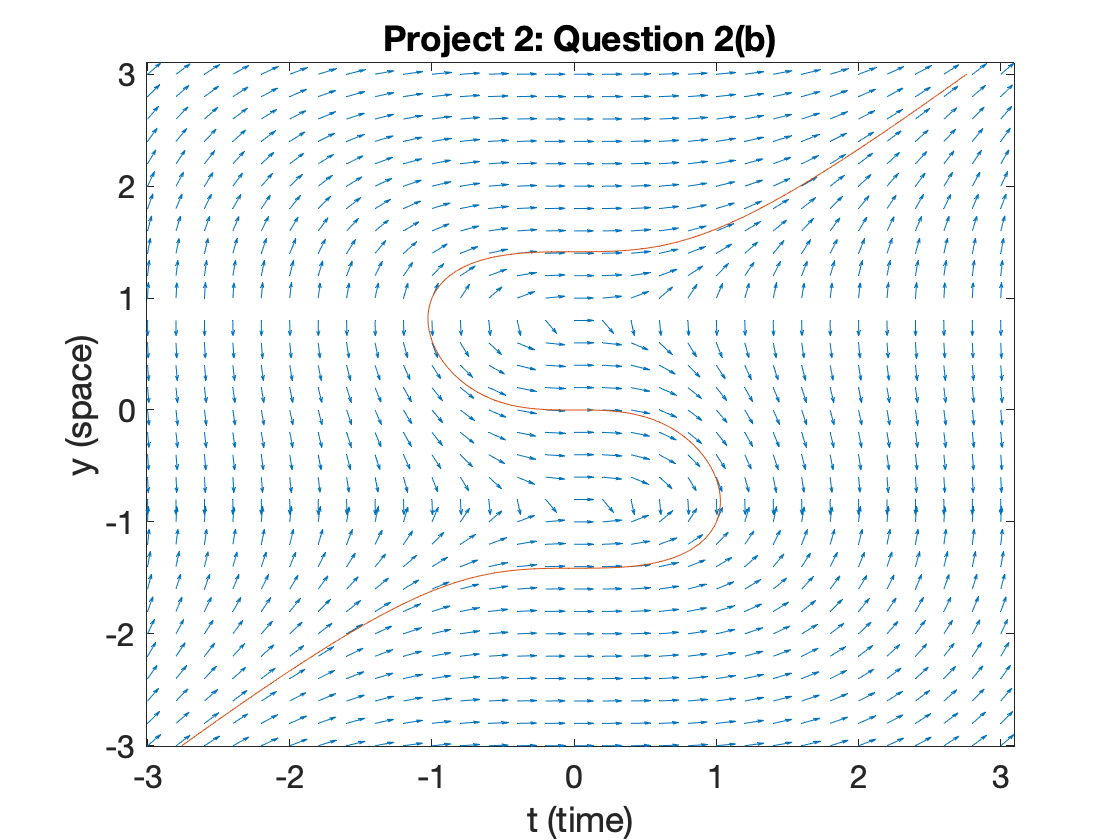

% code goes here
clear all % clear all variables in the workspace
set(0, 'DefaultAxesFontSize', 16) % increase font size in our figure


% define rate function using componentwise arithmetic
f = @(y,t) (3.*t.^2)./(3.*y.^2-2);
soln = @(t,y) t.^3 - y.^3 + 2*y;

% define grid for direction field
grid = -3:0.2:3;
[T,Y] = meshgrid(grid,grid);

% calculate slope (p'(t)) at each point in our grid
F = f(Y, T);

% normalize arrows to length 1
L = sqrt(1 + F.^2);

% At each point (T,P), draw the unit vector (1/L,F/L) and scale by 0.5
figure;
quiver(T, Y, 1./L, F./L,0.5)
hold on

fimplicit(soln,[-3,3,-3,3])

% label axes
axis tight
xlabel('t (time)')
ylabel('y (space)')
title('Project 2: Question 2(b)')

**(c)**

In order to estimate the value of $t=b$ where our numerical approximation will start to fail, we need to look at the denominator of the IVP to find when $3y^2 -2=0$ since our equation will be undefined at this point. The denominator is $0$ when $y=\pm \sqrt{\left(\frac{2}{3}\right)}\approx \pm 0\ldotp 82$. So, to find the value of $t$ when $y$ starts to fail, we must plug the negative $y$ parameter into the equation $y^3 -2y=t^3$ and solve for $t$:

                                                                    
$${\left(-\sqrt{\frac{2}{3}}\right)}^3 +2\sqrt{\frac{2}{3}}=t^3 \Longrightarrow t={\left({\left(-\sqrt{\frac{2}{3}}\right)}^3 +2\sqrt{\frac{2}{3}}\right)}^{\frac{1}{3}}$$
 

this gives us the value $t=1\ldotp 03$, so our numerical approximation starts failing at the point $y=-\sqrt{\frac{2}{3}}$ and $t=1\ldotp 03$. Similar analysis can be done for $y = -\sqrt{2/3}$ to get $t = -1.03$. However, we choose $t = 1.03$ because we assume that time moves forward. The reason we use $y=-\sqrt{\frac{2}{3}}$ is because time starts at 0 and increases and if you look at the y-t graph, the $y$ values are less than or equal to 0 when $t$ is positive.

**(d)**

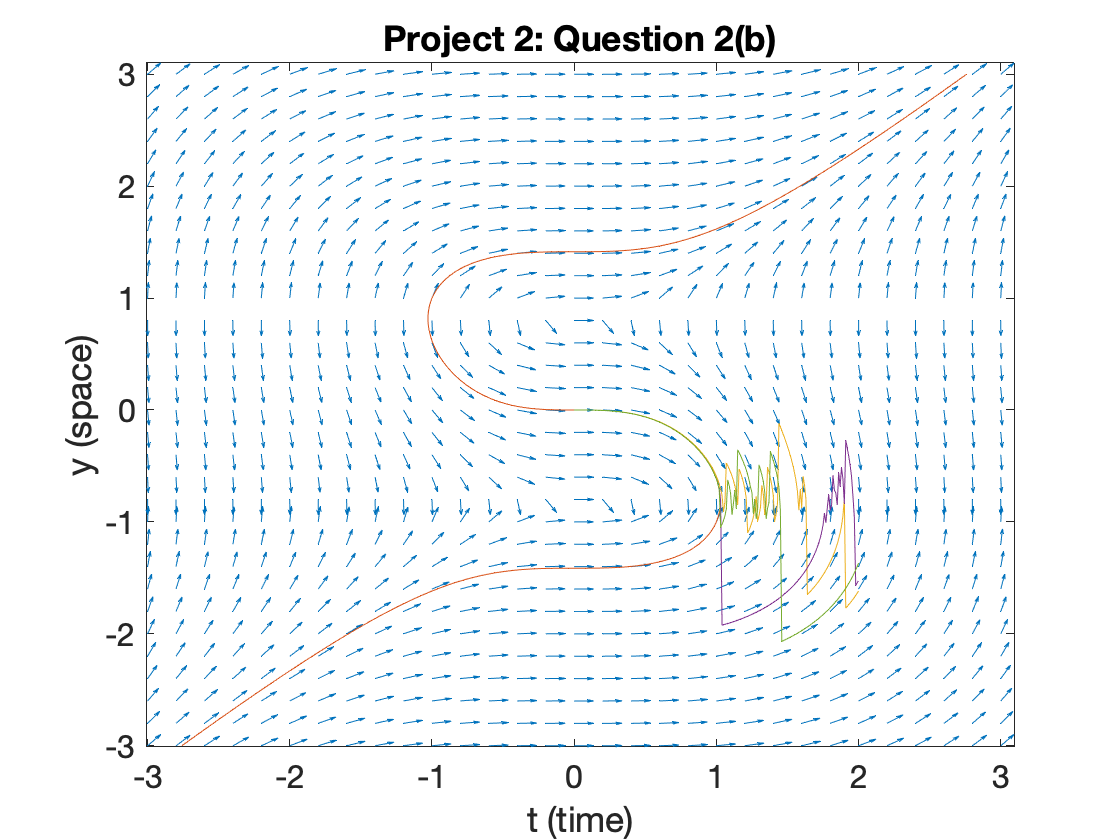

% code goes here
clear all % clear all variables in the workspace
set(0, 'DefaultAxesFontSize', 16) % increase font size in our figure

% define rate function using componentwise arithmetic
f = @(t,y) (3.*t.^2)./(3.*y.^2-2);
soln = @(t,y) t.^3 - y.^3 + 2*y;

% define grid for direction field
grid = -3:0.2:3;
[T,Y] = meshgrid(grid,grid);

% if you want to see what meshgrid is doing
%figure;
%plot(T,P,'o')

% calculate slope (p'(t)) at each point in our grid
F = f(T,Y);

% normalize arrows to length 1
L = sqrt(1 + F.^2);

t = linspace(0,2) ;
h = 0.01;
[t_arr, y_arr] = myEuler(0, 0, f, 2/h, h);
[t_arr_imp, y_arr_imp] = myImprovedEuler(0, f, 2/h, h);
[t_arr_rk, y_arr_rk] = myRK4(0, f, 2/h, h);

% At each point (T,P), draw the unit vector (1/L,F/L) and scale by 0.5
figure;
quiver(T, Y, 1./L, F./L,0.5)
hold on

fimplicit(soln,[-3,3,-3,3])
plot(t_arr, y_arr)
plot(t_arr_imp, y_arr_imp)
plot(t_arr_rk, y_arr_rk)

% label axes
axis tight
xlabel('t (time)')
ylabel('y (space)')
title('Project 2: Question 2(b)')

**(e)**

Euler's Method concerns itself with a point using the position of the point before it. So, when we have an undefined point where our approximation fails and the IVP is undefined, that means for the points after it, through Euler's Method, they exist, but they are neither valid nor useful. 

**(f)**

Now for $y\left(0\right)=1$. 

From part (a) we found that the general solution is $y^3 -2y=t^3 +C$, where $C$ is an arbituary constant dependent on initial conditions. Taking the condition $y(0) = 1$, we find that $C =-1$. Therefore the specific solution is $y^3 - 2y = t^3 -1$. 

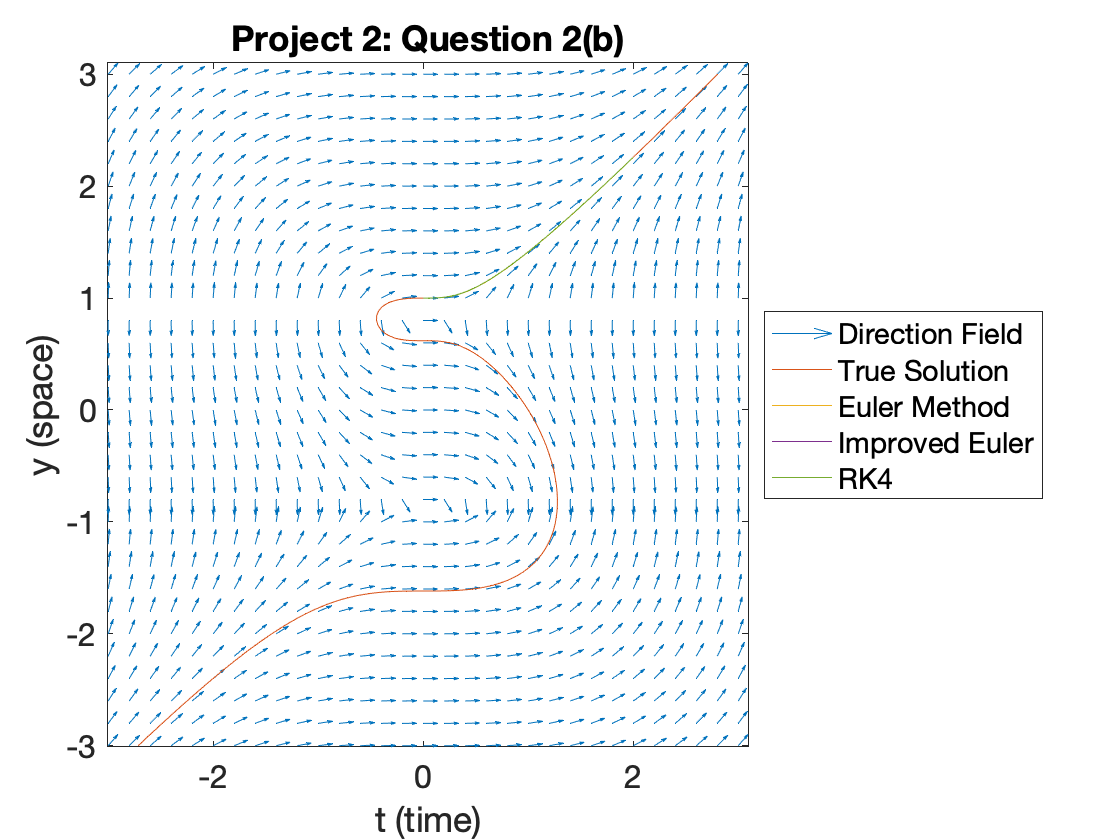

% code goes here
clear all % clear all variables in the workspace
set(0, 'DefaultAxesFontSize', 16) % increase font size in our figure

% define rate function using componentwise arithmetic
f = @(t,y) (3.*t.^2)./(3.*y.^2-2);
soln = @(t,y) t.^3 - y.^3 + 2*y - 1;

% define grid for direction field
grid = -3:0.2:3;
[T,Y] = meshgrid(grid,grid);

% if you want to see what meshgrid is doing
%figure;
%plot(T,P,'o')

% calculate slope (p'(t)) at each point in our grid
F = f(T,Y);

% normalize arrows to length 1
L = sqrt(1 + F.^2);

t = linspace(0,2) ;
h = 0.01;
[t_arr, y_arr] = myEuler(1, 0, f, 2/h, h);
[t_arr_imp, y_arr_imp] = myImprovedEuler(1, f, 2/h, h);
[t_arr_rk, y_arr_rk] = myRK4(1, f, 2/h, h);

% At each point (T,P), draw the unit vector (1/L,F/L) and scale by 0.5
figure;
quiver(T, Y, 1./L, F./L,0.5)
hold on

fimplicit(soln,[-3,3,-3,3])
plot(t_arr, y_arr)
plot(t_arr_imp, y_arr_imp)
plot(t_arr_rk, y_arr_rk)

% label axes
axis tight
xlabel('t (time)')
ylabel('y (space)')
title('Problem 2: Question 2(f)')
legend("Direction Field", "True Solution", "Euler Method", "Improved Euler", "RK4", "Location", "eastoutside")

**(g)**

[Typset summary paragraph here]

## Problem 3

**(a)**

The Euler approximation as derived in class reads $\hat{y}_{n+1} = \hat{y}_n + h f(t_n, \hat{y}_n)$. This was derived from the first order Taylor approximation. If we were to continue use an additional term of the Taylor series, we can truncate after the quadratic term to get a different Euler approximation: 

$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n +h\;f\left(t_n ,\hat{y} {\;}_n \right)+\frac{h^2 }{2}\;\left\lbrack \frac{\partial }{\partial t}f\left(t_n ,\hat{y} {\;}_n \right)+\frac{\partial }{\partial y}f\left(t_n ,\hat{y} {\;}_n \right)\frac{\partial y}{\partial t}\right\rbrack$. 

Since, $\partial{y}/\partial{t} = f(t_n, \hat{y}_n)$, we can rewrite the above equation as 

$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n +h\;f\left(t_n ,\hat{y} {\;}_n \right)+\frac{h^2 }{2}\;\left\lbrack \frac{\partial }{\partial t}f\left(t_n ,\hat{y} {\;}_n \right)+f\left(t_n ,\hat{y} {\;}_n \right)\frac{\partial }{\partial y}f\left(t_n ,\hat{y} {\;}_n \right)\right\rbrack$,

where $(t - t_n) = h$ and $y'(t_n) = f(t_n, \hat{y}_n)$. 

**(b)**

In our specific problem, $y'(t) = f(t_n, \hat{y}_n) = -2ty^2$. Therefore, we can rewrite the general expression in (a) as 

$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n +-2h\;t\;{\hat{y} }_n^2 +\frac{h^2 }{2}\left\lbrack -2\hat{y} {\;}_n^2 +\left(-2t_n \hat{y{\;}_n^2 } \right)\left(-4t_n \hat{y} {\;}_n \right)\right\rbrack$. 

This simplifies to

$\hat{y} {\;}_{n+1} =\hat{y} {\;}_n -\hat{y} {\;}_n^2 h\left(2t_n +h\right)+4t_n^2 \hat{y} {\;}_n^3 h^2$. 

Therefore $\hat{y} {\;}_{n+1} =\hat{y} {\;}_n -\hat{y} {\;}_n^2 h\left(2t_n +h\right)+4t_n^2 \hat{y} {\;}_n^3 h^2$ is the second order truncated Euler formula for our specific problem.

**(c)**

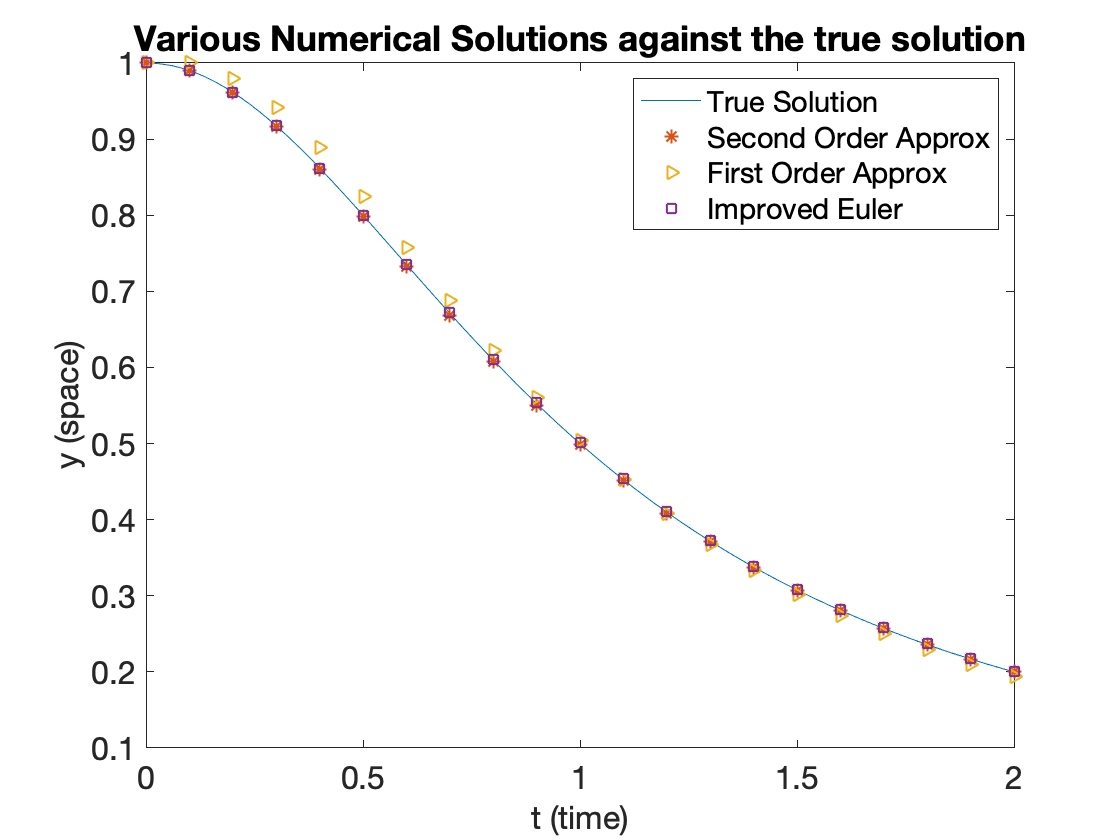

f = @(t,y) -2.*t.*y^2; % derivative 
h = 0.1 ; % step size 
[t_2, yapprox_2] = secondEuler(1, 0, 2/h, h) ; % call secondEuler function - function to evaluate second order Euler

% code from problem 1 here: 
f = @(t, y) -2.*t.*y.^2; % derivative 
soln1 = @(t) 1./(t.^2 + 1);  % solution 
t = linspace(0,2) ; % time grid 
h = 0.1; % step size 

% Euler and improved Euler solutions for comparison
[t_arr, y_arr] = myEuler(1, 0, f, 2/h, h); 
[t_arr_imp, y_arr_imp] = myImprovedEuler(1, f, 2/h, h);

% plot true solution and numerical approximations
figure
plot(linspace(0,2), soln1(linspace(0,2)))
hold on
scatter(t_2, yapprox_2, "Marker", "*", "LineWidth", 1)
scatter(t_arr, y_arr, "Marker", ">", "LineWidth",1)
scatter(t_arr_imp, y_arr_imp, "Marker", "square", "LineWidth",1)
legend("True Solution", "Second Order Approx", "First Order Approx", "Improved Euler")
xlabel("t (time)", "FontSize",16)
ylabel("y (space)", "FontSize",16)
title("Various Numerical Solutions against the true solution")


% Check convergence
% global error for step size h 
error_e2 = max(abs(soln1(linspace(0,2, 2/h+1)) - yapprox_2.'));
% calculate error for half of original step size 
h = h/2;
[t_2, yapprox_2_1] = secondEuler(1, 0, 2/h, h) ;
error_e2_1 = max(abs(soln1(linspace(0,2, 2/h+1)) - yapprox_2_1.'));
% check convergence
conv_euler2 = log2(error_e2/error_e2_1)

conv_euler2 = 2.0292

From this first convergence calculation we find that the order of convergence is $2$. Let us now analyze this for several subsequent step sizes. 

% Now let's do the analysis for varying step sizes where each step size is
% half the previous one 
h1 = 0.1;
error = @(sol, arr) max(abs(sol - arr.')); 
h = [h1 h1/2 h1/4 h1/8 h1/16 h1/32 h1/64];

[t,arr1] = secondEuler(1, 0, 2/h(1), h(1));
[t,arr2] = secondEuler(1, 0, 2/h(2), h(2));
[t,arr3] = secondEuler(1, 0, 2/h(3), h(3));
[t,arr4] = secondEuler(1, 0, 2/h(4), h(4));
[t,arr5] = secondEuler(1, 0, 2/h(5), h(5));
[t,arr6] = secondEuler(1, 0, 2/h(6), h(6));
[t,arr7] = secondEuler(1, 0, 2/h(7), h(7));

conv1 = log2(error(s1, arr1)/error(s2, arr2));
conv2 = log2(error(s2, arr2)/error(s3, arr3));
conv3 = log2(error(s3, arr3)/error(s4, arr4));
conv4 = log2(error(s4, arr4)/error(s5, arr5));
conv5 = log2(error(s5, arr5)/error(s6, arr6));
conv6 = log2(error(s6, arr6)/error(s7, arr7));
% table of convergence
colnames = ["h", "Order of Convergence"];
table(h(2:end)', [conv1, conv2, conv3, conv4, conv5, conv6]', 'VariableNames',colnames)

ans = 6×2 table
        h        Order of Convergence
    _________    ____________________

         0.05           2.0292       
        0.025           2.0152       
       0.0125           2.0087       
      0.00625           2.0042       
     0.003125           2.0021       
    0.0015625           2.0011       


From this calculation we determine that the order of convergence is $p = 2$ as expected! 

**(d)**

One might want to still use the improved Euler over this second order Taylor series method. The two methods have the same orders of convergences, meaning that the errors reduce with step size at the same rate. However, the benefit of the improved Euler method is that it averages over the $\hat{y}$ values at each of the end points of the curve, reducing the local truncation error when compared to the Euler method, as the curve is based on two points, the end points, instead of just one of the end points. Adding more and more terms reduces the error until the point where the equation of y(t) approaches an exact function $y(t)$(at least for small step size $h$), but there will be a high computational cost in having to compute more and more derivatives of $f = dy/dt$. Additionally, each subsequent order added to the Taylor series used to derive the Euler formula contributes a smaller effect on the error to the point wherre additional terms reduce the error by a negligable amount. 

## Problem 4

Climate change is becoming an increasingly important concern in our world right now, as the increase in global temperatures could have long-term, irreversible effects on our weather patterns and temperatures. Although fluctations in temeprature are natural, human activities like burning fossil fuels have caused for an overabundance of greenhouse gases in the atmosphere that can lead to disasterous effects on our global climate. It is important to model these changes in temperature to understand how the temperature changes as a function of the current temperature and efforts of the government to regulate emissions. 

Many experts predict that an increase in $2^o$C increase in temperature will cause the global temperature to depart from a current state of equilibrium and cause a positive feedback loop that results in a new equilibirum $6^{o}$ C higher than the current equilibrium. This would be a significant change and be disastrous for the species and climates on Earth. 

To model this, we have developed a differential equation that demonstrates the relationship between the rate of temperature change $dT/dt$, the current temperature $T$, and the impact of government regulation on the temperature $k$.  This variables have been found by experts to have the relationship

$\frac{\textrm{dT}}{\textrm{dt}}=-\frac{1}{10}\left(T-20\right)\left(T-22\right)\left(T-26\right)-k$,

where the $-1/10$ prefactor is a proportionality constant between the temperature and the rate of temperature change. The $k$ is subtracted from the temperature term based on the assumption that an increase in government regulation decreases the rate of temperature change. In other words, an increase in regulation should work to reverse an increase in temperature. In this form, one can also easily see the equilibrium solutions. It is assumed that the current equilibirum is at $T = 20^{o}$ C, but a $2^{o}$ temperature change will begin a positive feedback loop such that there is a new equilibrium temperature at $26^{o}$ C. At these points the rate of temperature change is constant unless there is an impact due to government regulations.

**(i) Baseline Figure**

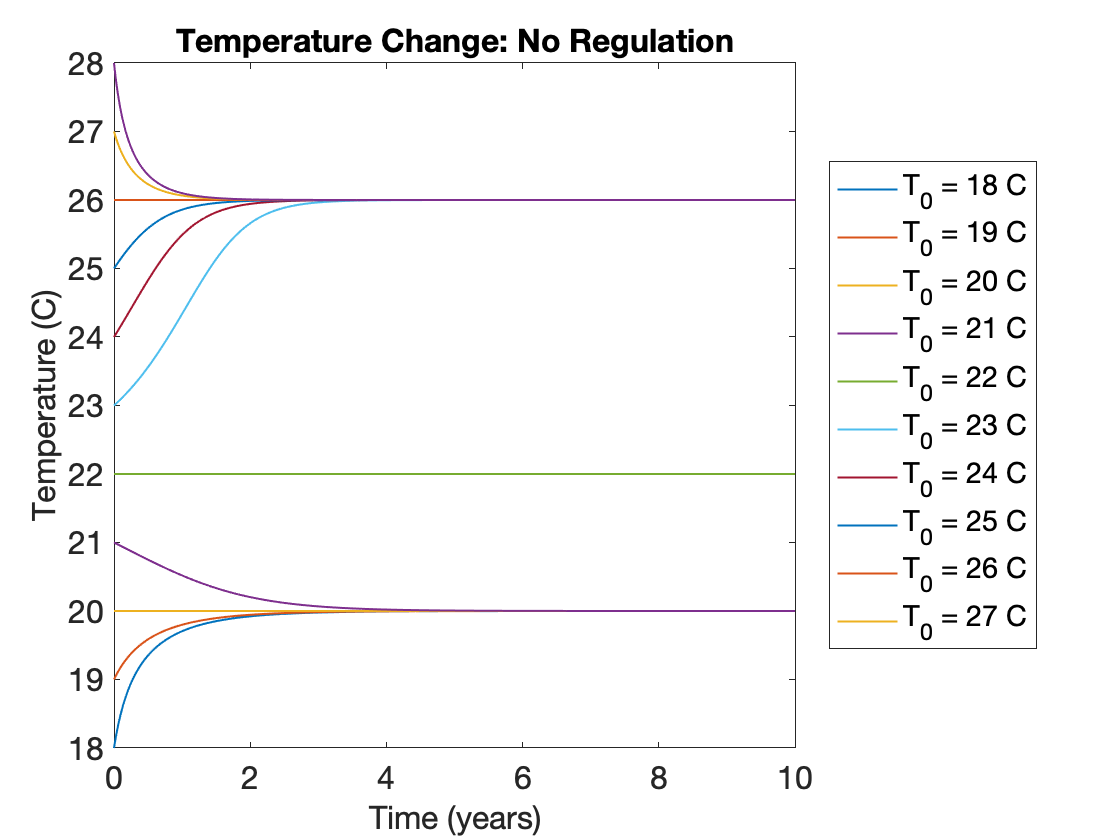

% code goes here: RK4 method 

% Differential equation for the model
f = @(t, T) -(1/10) * (T-20).*(T-22).*(T-26) ;
h = 0.01; % step size 
y0 = linspace(18, 28, 11) ;% initial temperatures 

% use for loop to plot solutions from RK4 
figure 
for y = 1:length(y0) 
    [t_arr_rk, y_arr_rk] = myRK4(y0(y), f, 10/h, h);
    plot(t_arr_rk, y_arr_rk, "LineWidth",1)
    hold on 
end

% legend  
legend(strcat("T_0 = ", num2str(y0(1)), " C"), strcat("T_0 = ", num2str(y0(2)), " C"), strcat("T_0 = ", num2str(y0(3)), " C"), strcat("T_0 = ", num2str(y0(4)), " C"), strcat("T_0 = ", num2str(y0(5)), " C"), strcat("T_0 = ", num2str(y0(6)), " C"),strcat("T_0 = ", num2str(y0(7)), " C"),strcat("T_0 = ", num2str(y0(8)), " C"),strcat("T_0 = ", num2str(y0(9)), " C"),strcat("T_0 = ", num2str(y0(10)), " C"), 'Location', 'eastoutside')
xlabel("Time (years)", "FontSize",16)
ylabel("Temperature (C)", "FontSize",16)
title("Temperature Change: No Regulation", "FontSize",16)

The above figure demonstrates the climate behavior with no government regulation. As shown above, the temperature either stabilizes at $20^{o}$ or $26^{o}$ depending on the temperature at time $t = 0$. For initial temperatures that are less than $22^{o}$, the global temperature will approach $20^{o}$. For temperatures higher than $22^{o}$, the global temperature will approach $26^{o}$. If the temperature starts out at $22^{o}$ in this time span, the temperature will remain at this $22^{o}$. This behavior demonstrates the importance of temperature control and the need to be conscious about emissions that are released into the atmosphere. Just a $2^{o}$ increase in temperature from the $20^{o}$ average will cause the global temperature to destabilize and approach the higher $26^{o}$ average within the 10 year time window. This is what is known as a positive feedback loop, as described above. 

We now consider the effect of increasing government regulation. The government holds a significant role in the behavior of climate change because they have the ability to impose laws and regulations on companies and individuals to reduce emissions that have the potential to increase the greenhouse gases released into the atmosphere. As described above, we assume that increasing regulation has the effect of reducing emissions and hence decreasing the global temperature. 

**(ii) Increased Regulation Figure**

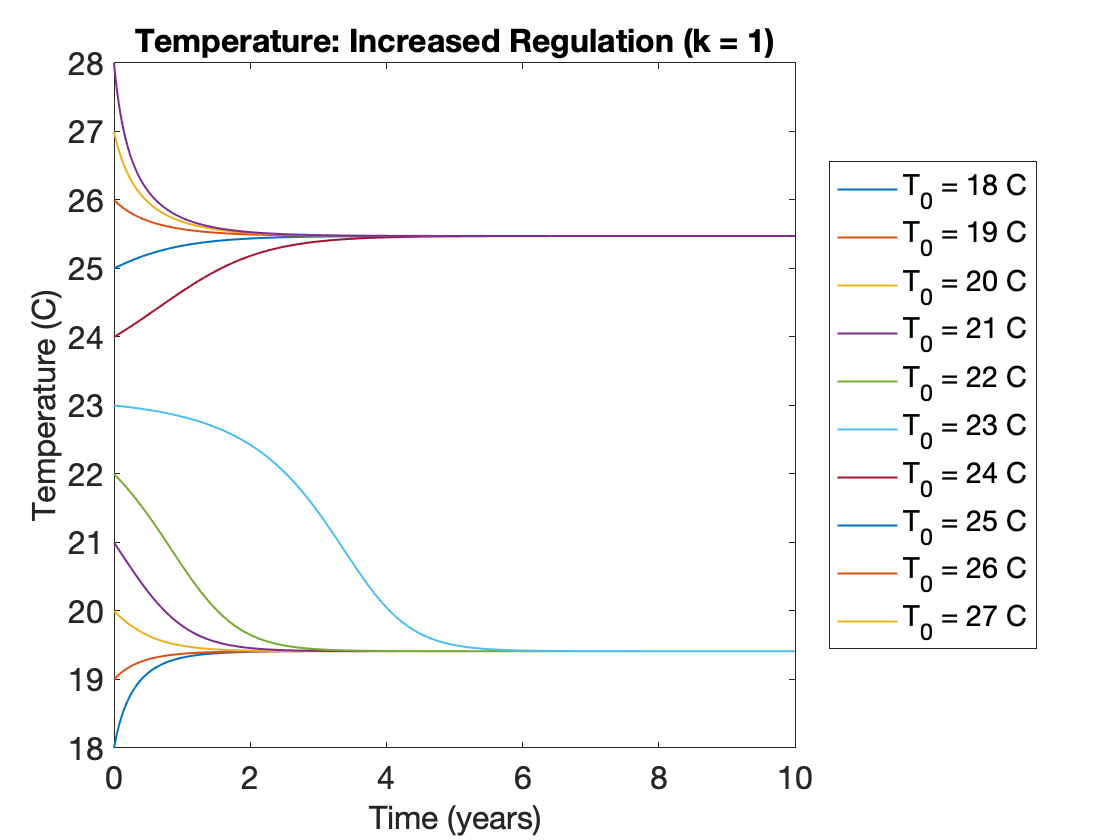

% code goes here
% For increased regulation, I defined a new function below: myRK4_2 that
% has an input k parameter 
f = @(t, T, k) -(1/10) * (T-20).*(T-22).*(T-26)-k ; % diff eq with regultion parameter k 
% set parameters 
h = 0.01;
k = 1;
y0 = linspace(18, 28, 11) ; % initial temperature array 
% for loop for plotting 
figure 
for y = 1:length(y0) 
    [t_arr_rk, y_arr_rk] = myRK4_2(y0(y), f, 10/h, h, k);
    plot(t_arr_rk, y_arr_rk, "LineWidth",1)
    hold on 
end
legend(strcat("T_0 = ", num2str(y0(1)), " C"), strcat("T_0 = ", num2str(y0(2)), " C"), strcat("T_0 = ", num2str(y0(3)), " C"), strcat("T_0 = ", num2str(y0(4)), " C"), strcat("T_0 = ", num2str(y0(5)), " C"), strcat("T_0 = ", num2str(y0(6)), " C"),strcat("T_0 = ", num2str(y0(7)), " C"),strcat("T_0 = ", num2str(y0(8)), " C"),strcat("T_0 = ", num2str(y0(9)), " C"),strcat("T_0 = ", num2str(y0(10)), " C"), 'Location', 'eastoutside')
xlabel("Time (years)", "FontSize",16)
ylabel("Temperature (C)", "FontSize",16)
title("Temperature: Increased Regulation (k = 1)", "FontSize",16)

It is clear from the above plot that increasing regulation changes the behavior of the global temperature within this ten year window. Here, we assume that the government regulation has the effect of changing the temperature at rate $k = 1^{o}$/year. While an initial temperature of $23^{o}$ was enough to cause the temperature to approach the higher $26^{o}$ equilibrium, with increased regulation, this temperature now leads to a stabilization at ~$20^{o}$. We also notice that the solution curves have shifted and there is a higher temperature threshold that must be attained in order to enter the positive feedback loop discussed previously. We also notice that the asymptotically stable equilibrium solutions, or stable temperature values, have been slightly offfset to be smaller than those in the baseline plot. In particular, the $20^{o}$ and $26^{o}$equilibrium temperature solution has now shifted down by about half a degree. 

On the other hand, we can analyze the effect of decreasing government regulation by the same magnitude. Now, we assume that the government regulation has been reduced with a negative effect of $1^{o}$/year. Namely, $k = -1^{o}$/year. This change implies that the effect of government regulation causes the temperature to increase. We see the effects in the following plot. 

**(i) Decreased Regulation Figure**

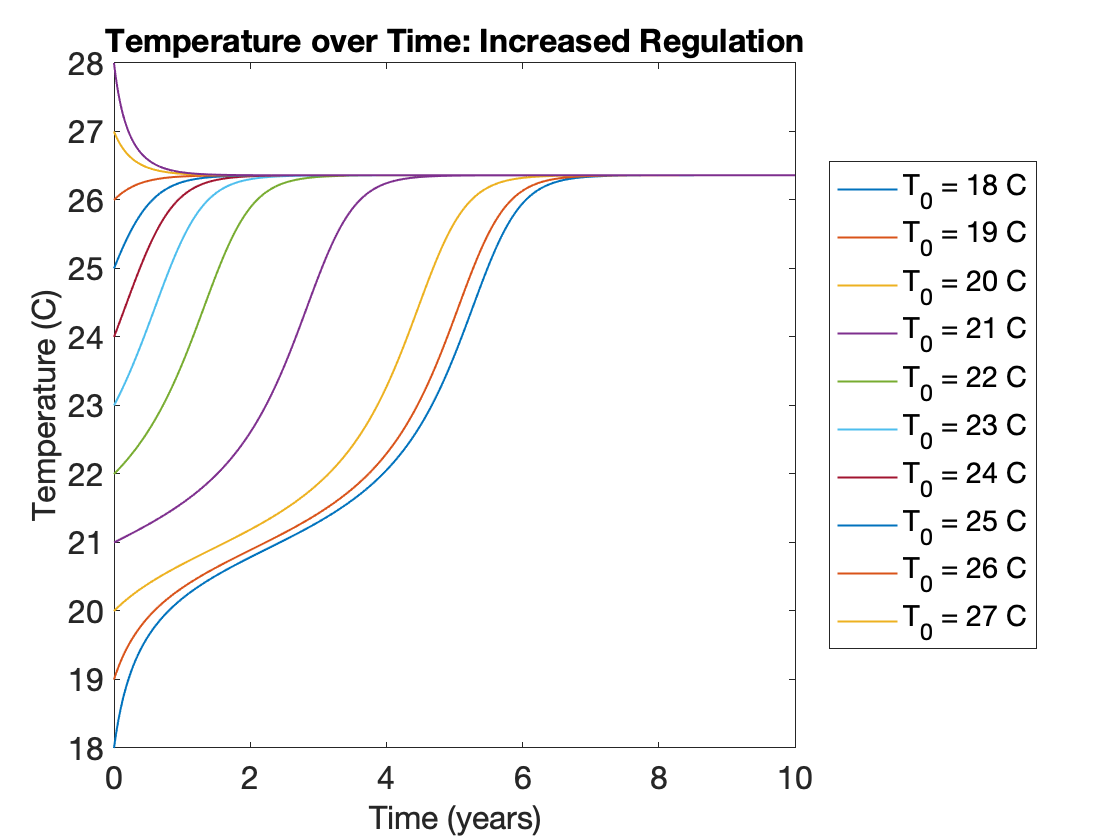

% code goes here
% I use the same function as the increasing case for the decreasing case  
f = @(t, T, k) -(1/10) * (T-20).*(T-22).*(T-26)-k ;
% set parameters 
h = 0.01;
k = -1;
y0 = linspace(18, 28, 11) ; % initial temperatures 

% plot solutions using for loop 
figure 
for y = 1:length(y0) 
    [t_arr_rk, y_arr_rk] = myRK4_2(y0(y), f, 10/h, h, k);
    plot(t_arr_rk, y_arr_rk, "LineWidth",1)
    hold on 
end
legend(strcat("T_0 = ", num2str(y0(1)), " C"), strcat("T_0 = ", num2str(y0(2)), " C"), strcat("T_0 = ", num2str(y0(3)), " C"), strcat("T_0 = ", num2str(y0(4)), " C"), strcat("T_0 = ", num2str(y0(5)), " C"), strcat("T_0 = ", num2str(y0(6)), " C"),strcat("T_0 = ", num2str(y0(7)), " C"),strcat("T_0 = ", num2str(y0(8)), " C"),strcat("T_0 = ", num2str(y0(9)), " C"),strcat("T_0 = ", num2str(y0(10)), " C"), 'Location', 'eastoutside')
xlabel("Time (years)", "FontSize",16)
ylabel("Temperature (C)", "FontSize",16)
title("Temperature over Time: Increased Regulation", "FontSize",16)

As shown above, the decrease in government regulation has a significant effect on the climate's behavior within this ten year time span. Regardless of the temperature at time $t = 0$, any initial temeprature in the range of interest ($18^{o}$ to $28^{o}$) stabilizes near ~$26^{o}$. This is deterimental to the environment because it would imply that there will be a $6^{o}$ increase in the global temperature from the ideal $20^{o}$. As a result, the government needs to ensure that they monitor the temperature and their regulation policies closely to ensure that they aid in maintaining a lower equilibrium temperature. 

The above plots demonstrate that the government plays a significant role in changing environmental behaviors. Increasing regulation increases the thresold requied for the environment to enter a positive feedback loop and stabilize at a higher equilibrium temperature. Decreasing regulation causes the environment to approach this higher equilibrium temperature regardless. As a result, the government must be mindful of the effect of their regulations and policies on the environment and be sure to increase regulation as needed to ensure that the temperature stabilizes at a manageble temperature for life and habitats across the globe. 

**"How do you know that your approximated solutions are even accurate?"**

We can calculate the error associated with the numerical solutions. In particular, the RK4 method has an error that is proportional to the step size to the fourth power. In other words, as the step size is halved, the error is reduced by a power of 8. Therefore, we know that the error must be on the order of $E \propto h^4$. In this case, we set $h = 0.01$, therefore our error is on order $E \approx 10^{-8}$. This error incorporates the error due to approximation and we thence know how much error we accumulate due to this numerical approximation. Since the error is on the order of $10^{-8$, the error is small and we know that our model is an accurate representation of the due solution.

## Functions

Function for 3c: 

% calculates an approximation to the second order truncated Euler equation 
% y0 is the initial y value 
% t0 is the initial t value
% N is the total number of steps
% h is the step size 

function [t, yapprox] = secondEuler(y0, t0, N, h)
    % set up empty vector for approximations 
    yapprox = NaN(N+1, 1) ;
    yapprox(1) = y0 ;
    t = t0:h:h*N; % time vector 
    % loop over each step 
    for i = 1:N
        % evaluate y(n+1) using the formula in (b)
        yapprox(i+1) = yapprox(i) - yapprox(i)^2*h*(2*t(i) + h) +4*t(i)^2*yapprox(i)^3*h^2;
    end
end


%% calculates an approximation to the differential equation y' = f(t,y) y(0) = y0 using RK4 method
% y0 is initial y value
% f is the function handle for the RHS of the diff eq
% N is the total number of steps
% h is the step size
function [t, yapprox] = myRK4_2(y0,f,N,h,k)
% set up empty vector to hold approximation
yapprox = NaN(N+1,1); 
 yapprox(1) = y0;
 % time vector
 t = 0:h:h*N;
 % loop over each step
 for i = 1:N
     % quadrature calculations
     K1 = f(t(i),yapprox(i),k);    %     f(tn, yn)
     yhat = yapprox(i)+(h/2)*K1; %     yn + h/2 K1
     K2 = f( t(i)+h/2, yhat,k);  %       f( tn+h/2, yn + h/2 K1)
     yhat2 = yapprox(i)+ (h/2)*K2; %   yn + h/2 K2
     K3 = f(t(i)+h/2, yhat2,k);  %       f(tn + h/2, yn + h/2 K2 
     K4 = f(t(i)+h, yapprox(i)+ h*K3, k);%f(tn+h, yn + h K3) 
     % approximation 
     yapprox(i+1) = yapprox(i) + (h/6)*(K1 + 2*K2 + 2*K3 + K4);
 end
end

## Honor Code

I have neither given or recieved unauthorized aid on this assignment.  

[Upload an image of your signature here]